# **各向异性的直流电型幻觉装置**

#### **        与**[**直流电型的隐身装置**](matlab:open('..\C 第三章 静磁场\C10_Isotropic_DC_Electric_Invisibility_Cloak.mlx'))**设计类似，设计目标为通过加载幻觉装置，使被幻觉物体具有与幻觉物体模型相同的电磁响应。**

**          ①原始物体模型：                                     ②幻觉物体模型：**

                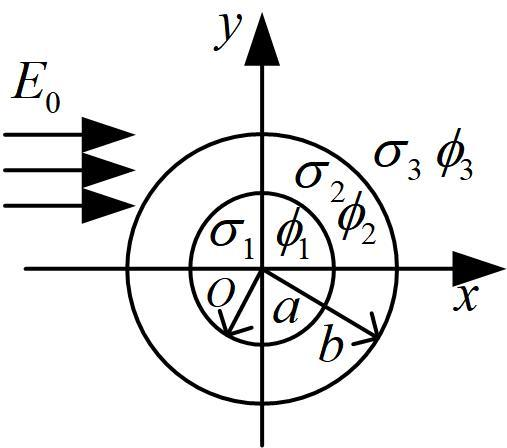                         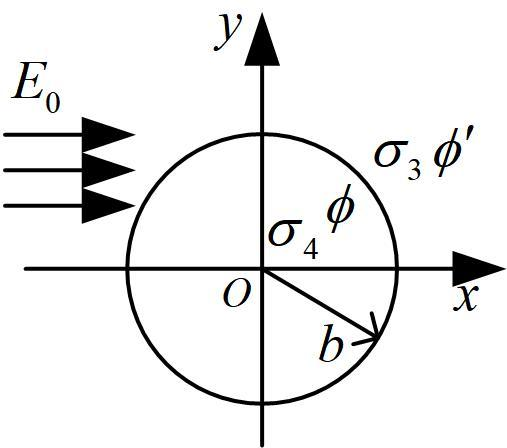

#### **        根据拉普拉斯方程——在稳恒电场中，各区域电势均满足**$\nabla^2 \phi_m =0$**，m=1,2,3；**

#### **        在各个边界分界面上有如下的边值关系**

#### 
$$\left\lbrace \begin{array}{cc}
{\phi_1 }_{\left|r=a\right.} ={\phi_2 }_{\left|r=a\right.} ， & {\sigma_1 \frac{\partial }{\partial r}\phi_1 }_{\left|r=a\right.} ={\sigma_{2r} \frac{\partial }{\partial r}\phi_2 }_{\left|r=a\right.} \\
{\phi_2 }_{\left|r=b\right.} ={\phi_3 }_{\left|r=b\right.} ， & {\sigma_{2r} \frac{\partial }{\partial r}\phi_2 }_{\left|r=b\right.} ={\sigma_3 \frac{\partial }{\partial r}\phi_3 }_{\left|r=b\right.} 
\end{array}\right.$$


#### **        原始物体模型的各个区域中的电势分布如下：**

####   
$$\begin{array}{l}
\phi_1 =\textrm{Arcos}\varphi \\
\phi_2 =\left(\textrm{Br}+\frac{C}{r}\right)\cos \varphi \\
\phi_3 =\left(-E_0 r+\frac{D}{r}\right)\cos \varphi 
\end{array}$$


#### **        幻觉物体模型的电势分布如下：**

####   
$$\begin{array}{l}
\phi_4 =A^{\prime } \textrm{rcos}\varphi \\
\phi^{\prime } =\left(\textrm{Mr}+\frac{N}{r}\right)\cos \varphi 
\end{array}$$


#### **        将各个区域的电势表达式代入边界条件。要实现幻觉，即要求**$\phi_3 =\phi^{\prime }$**；可求解出幻觉装置电导率的表达式为：**

####                              
$$\sigma_2 =\sqrt{\sigma_{2r\;\;} \sigma_{2\theta } }=\frac{n\left(\sigma_4 -\sigma_1 \right)}{2}\pm \frac{\sqrt{n^2 {\left(\sigma_4 -\sigma_1 \right)}^2 +4\sigma_1 \sigma_4 }}{2}$$


#### **         其中，**$n=\frac{{\left(b/a\right)}^{2l} +1}{{\left(b/a\right)}^{2l} -1}$**,**$l=\sqrt{\frac{\sigma_{2\theta } }{\sigma_{2r} }}$

#### **        仿真时，**$a=5\mathrm{mm}$**，**$b=10\mathrm{mm}$**，**$\sigma_1 =2$**，**$\sigma_3 =1$**，**$\sigma_4 =20$**。**

#### **        对于各向异性的情况，设**$l=\sqrt{\sigma_{2\theta } /\sigma_{2r} }=2$**，计算可得 **$\sigma_2 =22\ldotp 2$**、**$\sigma_{2\theta } =44\ldotp 4$**，**$\sigma_{2r} =11\ldotp 1$**；**

**        用pdetool仿真：**

- **幻形目标模型的磁势分布：**

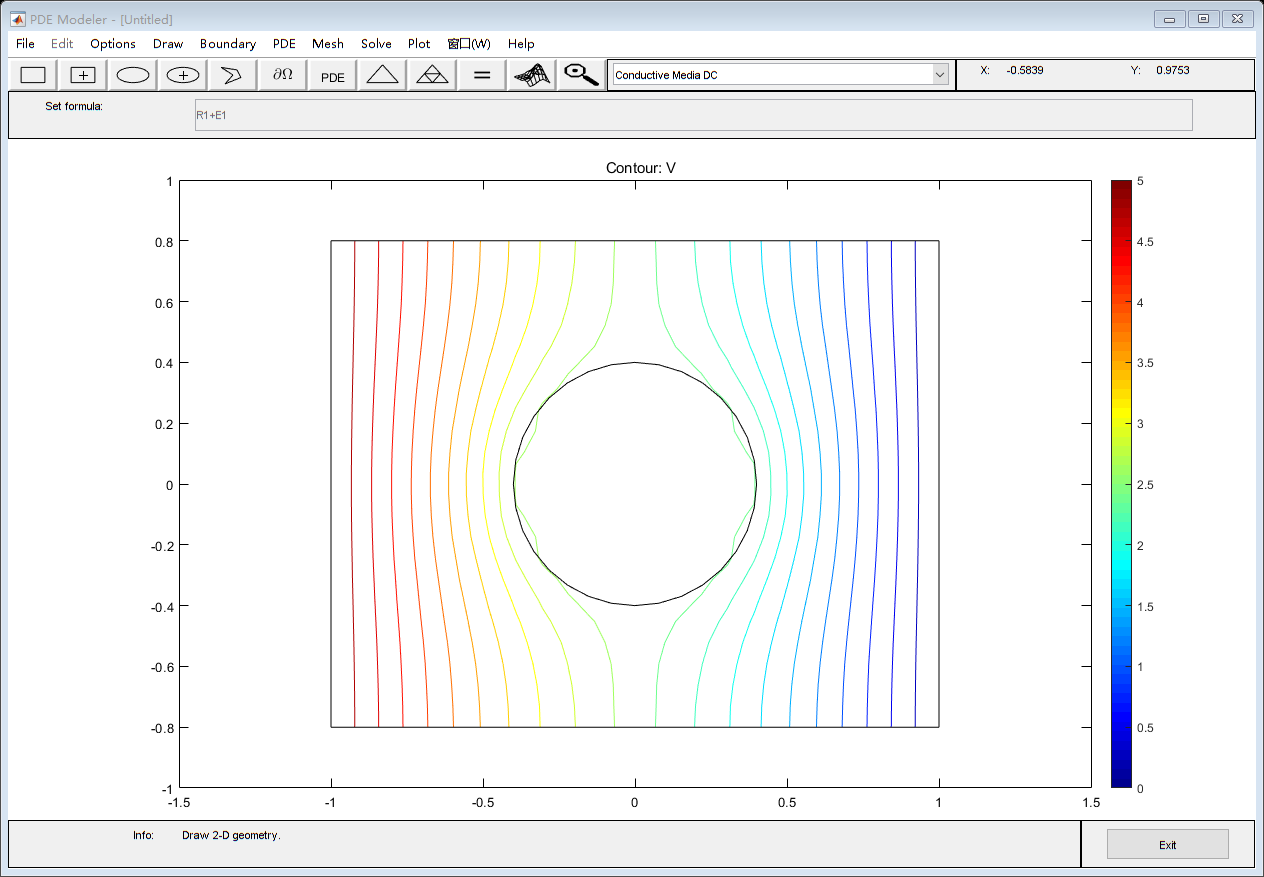

Illusion_Object_Model

- **使用幻形材料包裹金属柱的磁势分布：**

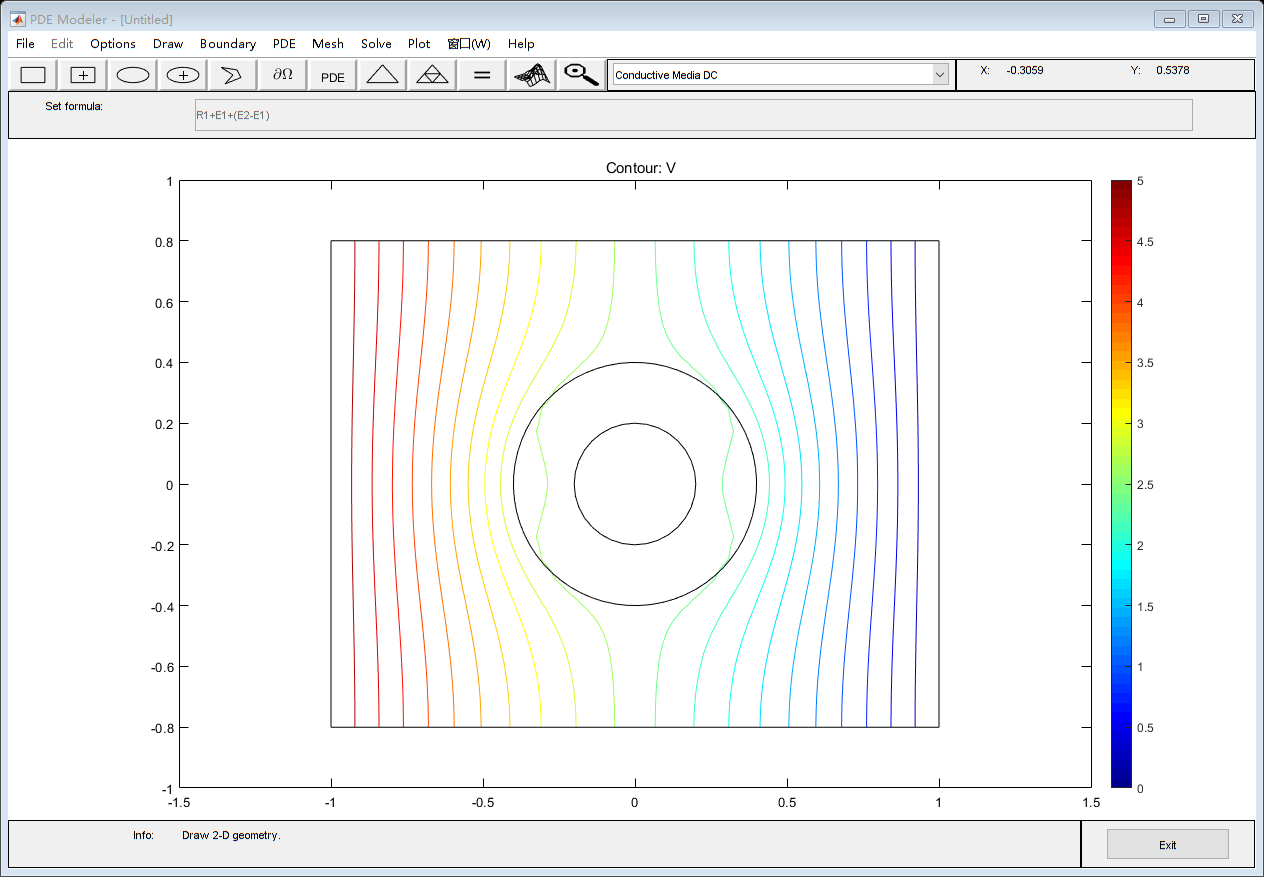

With_Illusion_Device

function With_Illusion_Device
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',8);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pdeellip(0,0,0.20000000000000001,0.20000000000000001,...
    0,'E1');
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,0.40000000000000002,0.40000000000000002,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+E1+(E2-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0!2!22.2',...
    '0.0!0.0!0.0',...
    '0!0!0',...
    '1.0!1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!2!22.2';...
    '0!0!0     '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6336','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 7 1 1 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end
function Illusion_Object_Model
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',8);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,0.40000000000000002,0.40000000000000002,...
    0,'E1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0!20',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!20';...
    '0!0   '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1476','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 7 1 1 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end
